digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', 'nndatasets','Dishes');
imds = imageDatastore(digitDatasetPath, 'IncludeSubfolders',true,'LabelSource','foldernames');

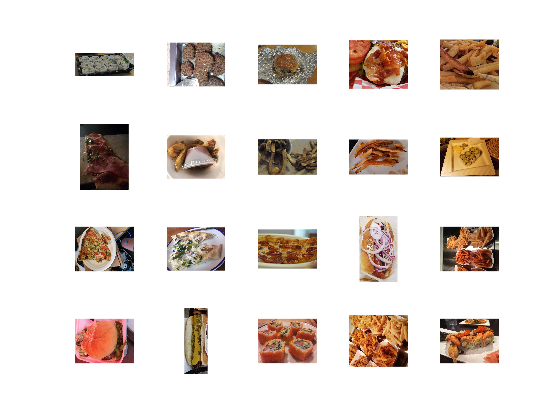

figure;
perm = randperm(978,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

labelCount = 9×2 table
        Label        Count
    _____________    _____

    caesar_salad       26 
    caprese_salad      15 
    french_fries      181 
    greek_salad        24 
    hamburger         238 
    hot_dog            31 
    pizza             299 
    sashimi            40 
    sushi             124 


img = readimage(imds,1);
size(img)

ans =    588   746     3


[imdsTrain, imdsValidation] = splitEachLabel (imds, 0.8, 'randomize' );
image_size = [64 64 3];
auds1 = augmentedImageDatastore(image_size, imdsTrain);
auds2 = augmentedImageDatastore(image_size, imdsValidation);

## Define Network Architecture

Define the convolutional neural network architecture.

layers = [
    imageInputLayer([64 64 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(9)
    softmaxLayer
    classificationLayer];

## Specify Training Options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',auds2, ...
    'ValidationFrequency',50, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train Network Using Training Data

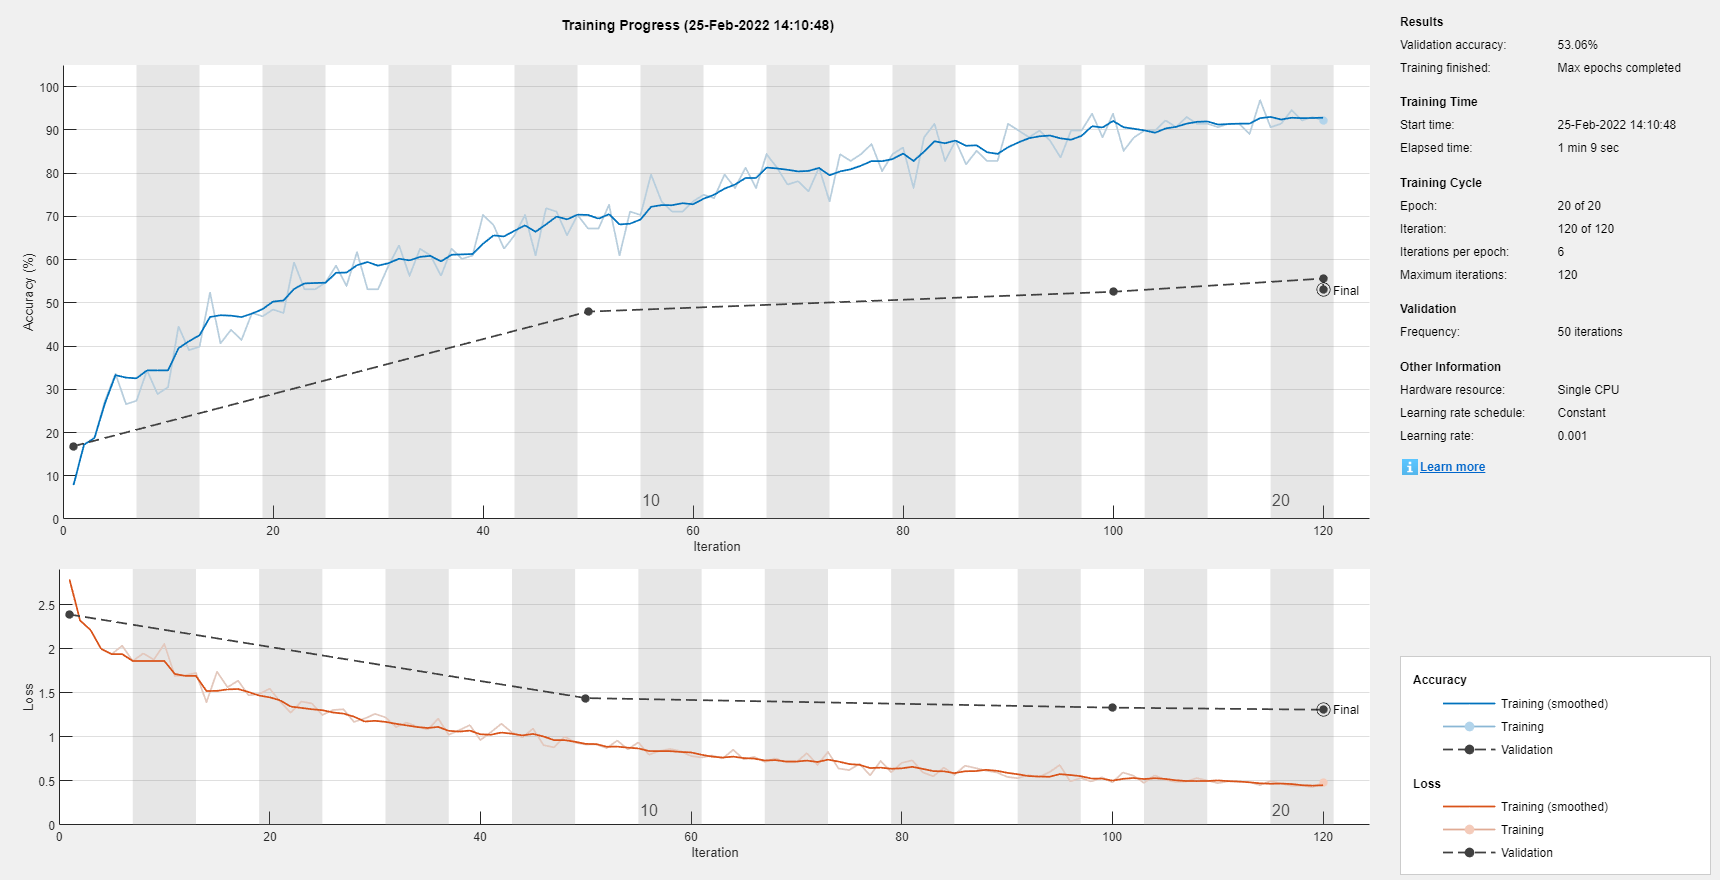

net = trainNetwork(auds1,layers,options);

## Classify Validation Images and Compute Accuracy

YPred = classify(net,auds2);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.5306